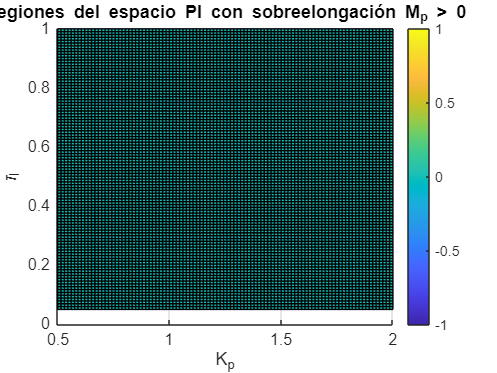

K = 1;

p = 1;
Kp = 10;
tauI = 0.1;

num = Kp * K * [1, 1/tauI];
den1 = conv([1 0 0], [1 p]);
den2 = [Kp*K, Kp*K/tauI, 0, 0];
den = den1 + den2;

sys = tf(num, den);
step(sys, 0:0.01:20);
title('Respuesta al escalón PI con K_p = 10, \tau_I = 0.1');